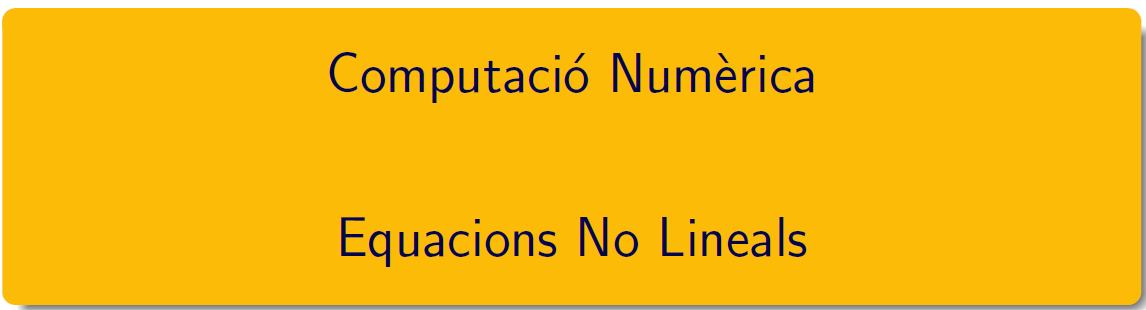

================================================================================

# Pràctica 7. Algorismes del punt fix

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-Lab6.pdf i en el document MN_full5.pdf, els podeu trobar en el campus virtual. 

Consulteu els documents [Cleve Moler, Zeroin Algorithms](https://blogs.mathworks.com/cleve/2015/10/12/zeroin-part-1-dekkers-algorithm/)  i el capítol 4 de [Numerical Computing with MATLAB](https://es.mathworks.com/moler/chapters.html), Cleve Moler per a una primera versió dels algorismes de la pràctica.

## 1 Mètode de la bisecció

#### Funció test

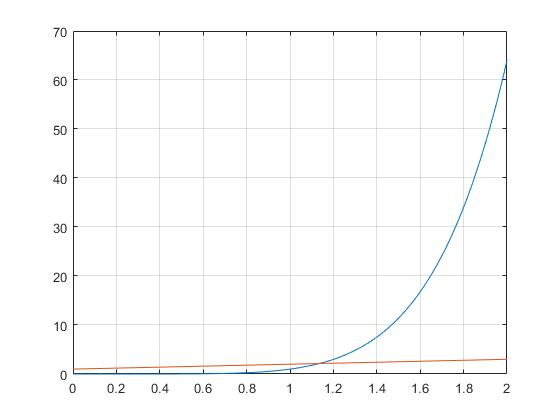

t = linspace(0,2);
plot(t,t.^6,t,t+1),grid

f=@(x)x.^6-x-1;
t=(1:0.1:1.5)';
disp(array2table([t,f(t)],"VariableNames",{'t','f(t)'}))

     t       f(t)  
    ___    ________

      1          -1
    1.1    -0.32844
    1.2     0.78598
    1.3      2.5268
    1.4      5.1295
    1.5      8.8906



#### Pràctica 11. Algorisme

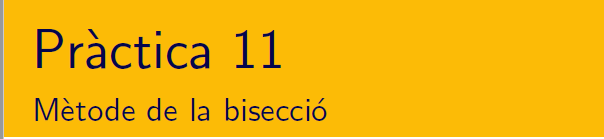

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la bisecció. Els arguments d'entrada han de ser l'interval inicial $$[a,b]$$i la funció $$f$$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el punt mig $$\alpha_{n+1}$$ i els valors de la funció per observar l'acompliment dels criteris d'aturada.

f=@(x)x.^6-x-1;
a = 1.1; b = 1.2; 
maxIt=52; tol = 0.00005;
xb = bisect(f,1.1,1.2,maxIt,tol)

    k          x                   f                   l
        1.100000000000000  -0.328438999999999                    
        1.200000000000000   0.785983999999999                    
    1   1.150000000000000   0.163060765624999   0.050000000000000
    2   1.125000000000000  -0.097713470458984   0.025000000000000
    3   1.137500000000000   0.028749282993316   0.012500000000000
    4   1.131250000000000  -0.035441712911068   0.006250000000000
    5   1.134375000000000  -0.003588776076577   0.003125000000000
    6   1.135937500000000   0.012519278729156   0.001562500000000
    7   1.135156250000000   0.004450049558158   0.000781250000000
    8   1.134765625000000   0.000426841528573   0.000390625000000
    9   1.134570312500000  -0.001581915423921   0.000195312500000
   10   1.134667968750000  -0.000577774066768   0.000097656250000
   11   1.134716796875000  -0.000075525559076   0.000048828125000
        1.134741210937500   0.000175643160977   0.000024414062500


xb =        1.1347


## 2 Mètode de la tangent

#### Funció test

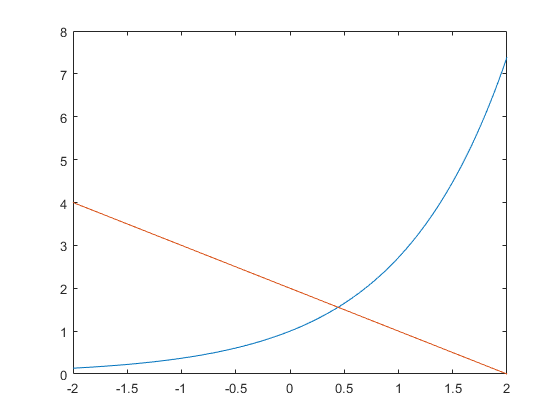

format shortG
t = linspace(-2,2);
plot(t,exp(t),t,2-t)

f=@(x)exp(x)-2+x;
t=(0:0.1:1)';
disp(array2table([t,f(t)],"VariableNames",{'t','f(t)'}))

     t       f(t)  
    ___    ________

      0          -1
    0.1    -0.79483
    0.2     -0.5786
    0.3    -0.35014
    0.4    -0.10818
    0.5     0.14872
    0.6     0.42212
    0.7     0.71375
    0.8      1.0255
    0.9      1.3596
      1      1.7183



#### Pràctica 12. Algorisme

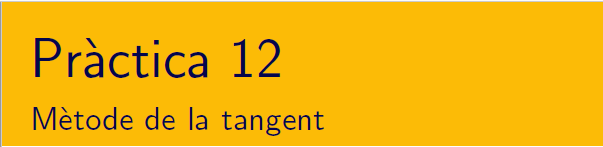

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la tangent. Els arguments d'entrada han de ser lel valor inicial $x_0$ i les funcions $$f$$i $f^\prime$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el valor calculat $$x_{n+1}$$ i els valors de la funció per observar l'acompliment dels criteris d'aturada.

f=@(x)exp(x)-2+x;
fp=@(x)exp(x)+1;
a=0.4; b=0.5; 
maxIt=52; tol = 5e-12;
xn = newton(f,fp,a,tol,maxIt)

    k          x                   f                   l
    0   0.400000000000000  -0.108175302358730                    
    1   0.443412083707625   0.001426318064278   0.043412083707625
    2   0.442854495698488   0.000000242151722   0.000557588009136
    3   0.442854401002391   0.000000000000007   0.000000094696097
    4   0.442854401002389  -0.000000000000000   0.000000000000003


xn =       0.44285


## 3 Mètode de la secant

#### Funció test

t = linspace(0,2);
plot(t,t.^6,t,t+1),grid

f=@(x)x.^6-x-1;
t=(1:0.1:1.5)';
disp(array2table([t,f(t)],"VariableNames",{'t','f(t)'}))

     t       f(t)  
    ___    ________

      1          -1
    1.1    -0.32844
    1.2     0.78598
    1.3      2.5268
    1.4      5.1295
    1.5      8.8906



#### Pràctica 13. Algorisme

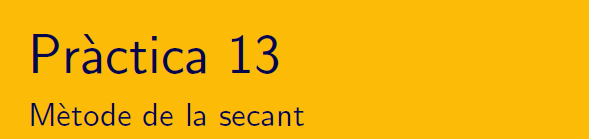

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la secant. Els arguments d'entrada han de ser els valors inicials $x_1$ i $x_2$ i  la funció $$f$$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el valor calculat $$x_{n+1}$$ i els valors de la funció pels valors de la funció per observar l'acompliment dels criteris d'aturada.

f=@(x)x.^6-x-1;
a = 1.1; b = 1.2; 
maxIt=52; tol = 0.00005;
xs = secant(f,a,b,tol,tol,maxIt)

    k          x                   f                   l
        1.100000000000000  -3.284389999999993e-01                    
        1.200000000000000   7.859839999999993e-01                    
    1   1.129471663811677  -5.335363960159545e-02   0.070528336188323
    2   1.133954893507509  -7.899003471724564e-03   0.004483229695833
    3   1.134733978985847   1.012386866792170e-04   0.000779085478338
    4   1.134724120085445  -1.884289710929465e-07   0.000009858900403


xs =        1.1347


## Mètode de la iteració simple 

#### Funció test

Per a resoldre $x^6=x+1$  es proposen els mètodes


$$
\mathbf{(f1)}~x_{n+1} = x_n^6-1\,,\qquad \mathbf{(f2)}~x_{n+1} = \sqrt[6]{x_n+1}\,,$$
 

f=@(x)x.^6-x-1;
t=(1:0.1:1.5)';
disp(array2table([t,f(t)],"VariableNames",{'t','f(t)'}))

#### Pràctica 14. Algorisme

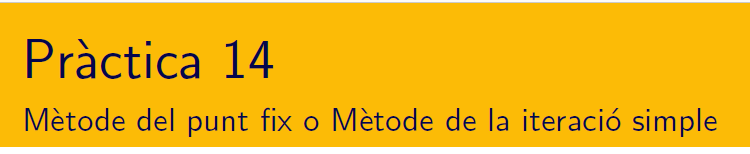

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la iteració simple. Els arguments d'entrada han de ser el valor inicials $x_1$, la funció $$f$$i la funció $g$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el valor calculat $$x_{n+1}$$ i els valors de la funció  per observar l'acompliment dels criteris d'aturada.

% Pràctica 7 d'abril 2021

#### Pràctica 15. Teorema de convergència

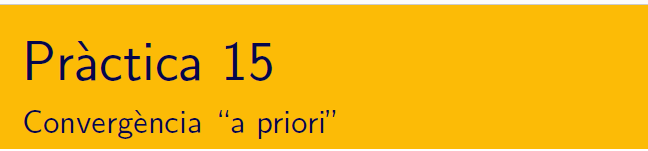

Escriure un `live script de MATLAB® `que:

- analitzi la convergència "a priori" del mètode de la iteració simple $x_{n+1} = g(x_n)$ consistent per a l'equació $f(x)=0$ i obtingui l'interval maximal de convergència en funció de la condició inicial $x_0$

- obtenir el nombre d'iteracions necessàries per acomplit el criteri d'aturada  $tol_x <\epsilon$

% Pràctica 7 d'abril 2021 practicar el que hem fet a clase de lab